clc
clear variables
close all

mm_to_m = 1/1000;
J_thickness = 9*mm_to_m;
% J_thickness = 8.6*mm_to_m;
width = 40*mm_to_m;

constants = containers.Map;
constants('youngs_mod') = 25*10^9;%5*10^9%25*10^9 %29*10^9;%250*10^9;
constants('shear_mod') = 10*10^9;%1.9*10^9%10*10^9;
constants('shape_factor') = 6/5;

% forces = containers.Map()
% F = 2000;
% Fa = pi;
% V = F*cos(Fa);
% H = F*sin(Fa);
% forces('f') = [V; H];

forces = containers.Map()
F = 2000; %/(360);
Fa = pi;
V = F*sin(Fa);
H = F*cos(Fa);
forces('f') = [V; H];

s1 = containers.Map;
s1('thickness') = J_thickness;
s1('length') = (48.29)*mm_to_m;

s1('width') = width;
s1('beam_angle') = 31.98*(pi/180); % rad
s1('couple') = 0; % init
s1('boundary_angle') = 0;
s1('boundary_defV') = 0;
s1('boundary_defH') = 0;
straight0 = Straight(constants, s1);

c1 = containers.Map();
c1('length') = 95.43*mm_to_m;
c1('height') = 43.8*mm_to_m;
c1('chord') = sqrt(c1('height')^2+c1('length')^2);
c1('thickness') = J_thickness;
c1('radius') = (247.82*mm_to_m) + J_thickness/2;
c1('width') = width;
c1('sweep_angle') = 2*asin(0.5*c1('chord')/c1('radius'));
% c1('start_angle') = pi/2-c1('sweep_angle');
% c1('end_angle') = pi/2;
% c1('start_angle') = -pi/2+c1('sweep_angle');
% c1('end_angle') = -pi/2;
c1('start_angle') = c1('sweep_angle');
c1('end_angle') = 0;
c1('boundary_angle') = 0;
c1('boundary_defV') = 0;
c1('boundary_defH') = 0;
c1('couple') = 0; % init
curved = Curved(constants, c1);

c2 = containers.Map();
c2('length') = 20.38.*mm_to_m;
c2('height') = 21*mm_to_m;
c2('chord') = sqrt(c2('height')^2+c2('length')^2);
c2('thickness') = J_thickness;
c2('radius') = 33.25*mm_to_m;
c2('width') = width;
c2('sweep_angle') = 2*asin(0.5*c2('chord')/c2('radius'));
% c2('start_angle') = 0;
% c2('end_angle') = c2('sweep_angle');
c2('start_angle') = -pi/2 + c2('sweep_angle');
c2('end_angle') = -pi/2;
c2('boundary_angle') = 0;
c2('boundary_defV') = 0;
c2('boundary_defH') = 0;
c2('couple') = 0; % init
curved2 = Curved(constants, c2);

% example using stitch to replicate the manual stitching below
sections = containers.Map()
sections('1') = curved;
% sections('2') = straight0;
% sections('3') = curved2;

[x_base, y_base, x_deformed, y_deformed] = stitch(sections, forces);
plot(x_base, y_base)
hold on
plot(x_deformed, y_deformed)
axis('equal')
legend('static', 'deformed', location='southeastoutside')

clf

mm_to_m = 1/1000;
S_thickness = .5*mm_to_m;
S_thickness_2 = .5*mm_to_m;
J_thickness = 0.5*mm_to_m;
% J_thickness = 8.6*mm_to_m;
width = 40*mm_to_m;

constants = containers.Map;
constants('youngs_mod') = 70*10^9;%5*10^9%25*10^9 %29*10^9;%250*10^9;
constants('shear_mod') = 10*10^9;%1.9*10^9%10*10^9;
constants('shape_factor') = 6/5;

% forces = containers.Map()
% F = 4300; %/(360);
% Fa = 3*pi/4; % force vector space is rotated by +90 deg to plot atm!
% V = -1*F*cos(Fa); % - as 'v' dimension flipped for sign convention with text book
% H = F*sin(Fa);
% forces('f') = [V; H];

forces = containers.Map()
F = 100; %/(360);
Fa = pi/2; % force vector space is rotated by +90 deg to plot atm!
V = F*sin(Fa); % - as 'v' dimension flipped for sign convention with text book
H = F*cos(Fa);
forces('f') = [V; H];

s1 = containers.Map;
s1('thickness') = S_thickness;
s1('length') = (10)*mm_to_m;
s1('width') = width;
s1('beam_angle') = 10*(pi/180); % rad
s1('couple') = 0; % init
s1('boundary_angle') = 0;
s1('boundary_defV') = 0;
s1('boundary_defH') = 0;
straight1 = Straight(constants, s1);


% FOR A CURVED SECTION, THE  start_angle IS THE LOADED END
c1 = containers.Map();
c1('length') = 20*mm_to_m;
c1('height') = 20*mm_to_m;
c1('thickness') = J_thickness;
c1('radius') = 8.25*mm_to_m;
c1('width') = width;
c1('chord') = sqrt(c1('height')^2+c1('length')^2);
c1('sweep_angle') = 2*asin(0.5*c1('chord')/c1('radius'));
% c1('start_angle') = -pi;
% c1('end_angle') = -pi/2;
% c1('start_angle') = 0;
% c1('end_angle') = pi/2;
c1('start_angle') = 0;
c1('end_angle') = -pi/2;
c1('boundary_angle') = 0;
c1('boundary_defV') = 0;
c1('boundary_defH') = 0;
c1('couple') = 0; % init
curved = Curved(constants, c1);


c2 = containers.Map();
c2('length') = 8.5.*mm_to_m;
c2('height') = 8.5.*mm_to_m;
c2('chord') = sqrt(c2('height')^2+c2('length')^2);
c2('thickness') = J_thickness;
c2('radius') = 8.5.*mm_to_m;
c2('width') = width;
c2('sweep_angle') = 2*asin(0.5*c2('chord')/c2('radius'));
% c2('start_angle') = pi/2;
% c2('end_angle') = 0;
% c2('start_angle') = -pi/2;
% c2('end_angle') = -pi;
c2('start_angle') = 0;
c2('end_angle') = pi/2;
c2('boundary_angle') = 0;
c2('boundary_defV') = 0;
c2('boundary_defH') = 0;
c2('couple') = 0; % init
curved2 = Curved(constants, c2);

s2 = containers.Map;
s2('thickness') = S_thickness;
s2('length') = (10)*mm_to_m;

s2('width') = width;
s2('beam_angle') = 10*(pi/180); % rad
s2('couple') = 0; % init
s2('boundary_angle') = 0; 
s2('boundary_defV') = 0;
s2('boundary_defH') = 0;
straight2 = Straight(constants, s2);

sections = containers.Map()
% sections('1') = straight1;
sections('1') = curved;
% sections('2') = curved2;
% sections('2') = straight2;

[x_base, y_base, x_deformed, y_deformed, moment, ang, strain_e] = stitch(sections, forces);
title('deflection')
plot(x_base, y_base)
hold on
plot(x_deformed, y_deformed)
xlabel('m')
ylabel('m')
legend('static', 'deformed', location='southeastoutside')
axis('equal')
hold off
% plot(x_base, strain_e)
title('strain E')
plot(x_base, moment)
title('moment')
plot(x_base, ang)
title('angle')

mnt = cross([.118 .03 0], [228.8; 870; 0]);

% PRELIM ENERGY FIGURES AT 20deg DORSIFLECTION, 900N TOE FORCE, 2150N MOTOR
% FORCE
clf
mm_to_m = 1/1000;
S_thickness = 4.5*mm_to_m;
width = 45*mm_to_m;

constants = containers.Map;
constants('youngs_mod') = 29*10^9;%5*10^9%25*10^9 %29*10^9;%250*10^9;
constants('shear_mod') = 10*10^9;%1.9*10^9%10*10^9;
constants('shape_factor') = 6/5;

forces = containers.Map();
F = 600;
Fa = (110)*pi/180; 
V = F*sin(Fa);
H = F*cos(Fa);
forces('f') = [V; H];

s1 = containers.Map;
s1('thickness') = S_thickness;
s1('length') = (114)*mm_to_m; %(67)*mm_to_m;
s1('width') = width;
s1('beam_angle') = -0.12; %*(pi/180); % rad
s1('couple') = 0; % init
s1('boundary_angle') = 0;
s1('boundary_defV') = 0;
s1('boundary_defH') = 0;
straight1 = Straight(constants, s1);

sections = containers.Map();
sections('1') = straight1;

[x_base, y_base, x_deformed, y_deformed, moment, ang, strain_e] = stitch(sections, forces);

sV =          0   -0.0001   -0.0002   -0.0004   -0.0005   -0.0006   -0.0007   -0.0008   -0.0010   -0.0011   -0.0012   -0.0013   -0.0014   -0.0016   -0.0017   -0.0018   -0.0019   -0.0021   -0.0022   -0.0023   -0.0024   -0.0025   -0.0027   -0.0028   -0.0029   -0.0030   -0.0031   -0.0033   -0.0034   -0.0035   -0.0036   -0.0037   -0.0039   -0.0040   -0.0041   -0.0042   -0.0043   -0.0045   -0.0046   -0.0047   -0.0048   -0.0050   -0.0051   -0.0052   -0.0053   -0.0054   -0.0056   -0.0057   -0.0058   -0.0059


v_base =          0   -0.0001   -0.0002   -0.0004   -0.0005   -0.0006   -0.0007   -0.0008   -0.0010   -0.0011   -0.0012   -0.0013   -0.0014   -0.0016   -0.0017   -0.0018   -0.0019   -0.0021   -0.0022   -0.0023   -0.0024   -0.0025   -0.0027   -0.0028   -0.0029   -0.0030   -0.0031   -0.0033   -0.0034   -0.0035   -0.0036   -0.0037   -0.0039   -0.0040   -0.0041   -0.0042   -0.0043   -0.0045   -0.0046   -0.0047   -0.0048   -0.0050   -0.0051   -0.0052   -0.0053   -0.0054   -0.0056   -0.0057   -0.0058   -0.0059


y_base =          0   -0.0001   -0.0002   -0.0004   -0.0005   -0.0006   -0.0007   -0.0008   -0.0010   -0.0011   -0.0012   -0.0013   -0.0014   -0.0016   -0.0017   -0.0018   -0.0019   -0.0021   -0.0022   -0.0023   -0.0024   -0.0025   -0.0027   -0.0028   -0.0029   -0.0030   -0.0031   -0.0033   -0.0034   -0.0035   -0.0036   -0.0037   -0.0039   -0.0040   -0.0041   -0.0042   -0.0043   -0.0045   -0.0046   -0.0047   -0.0048   -0.0050   -0.0051   -0.0052   -0.0053   -0.0054   -0.0056   -0.0057   -0.0058   -0.0059


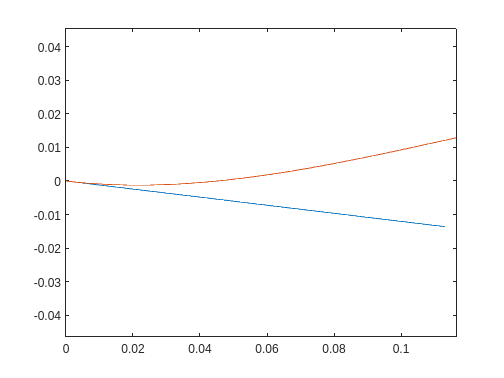

title('deflection')
plot(x_base, y_base)
hold on
plot(x_deformed, y_deformed)
axis('equal')
hold off

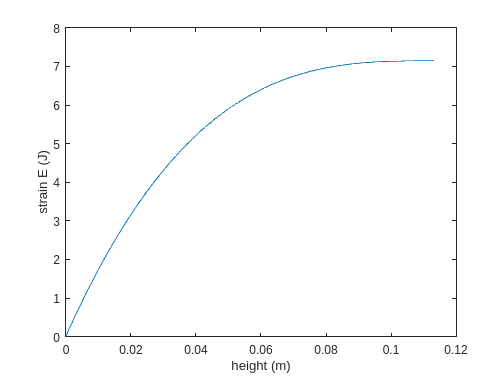

plot(x_base, strain_e)
xlabel('height (m)')
ylabel('strain E (J)')

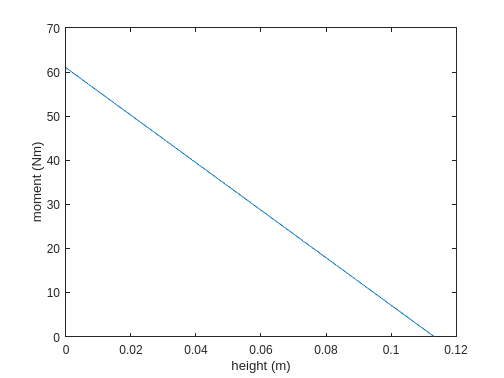

plot(x_base, moment)
xlabel('height (m)')
ylabel('moment (Nm)')

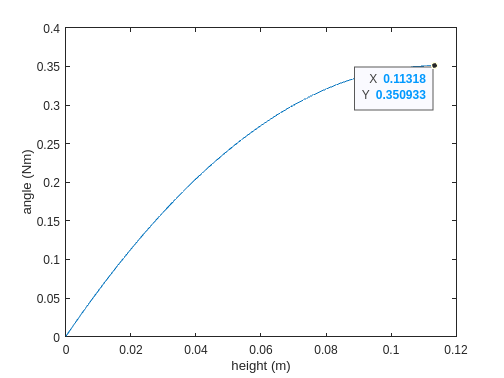

plot(x_base, ang)
xlabel('height (m)')
ylabel('angle (Nm)')

clf
mm_to_m = 1/1000;
S_thickness = 4.5*mm_to_m;
width = 40*mm_to_m;

constants = containers.Map;
constants('youngs_mod') = 29*10^9;%5*10^9%25*10^9 %29*10^9;%250*10^9;
constants('shear_mod') = 10*10^9;%1.9*10^9%10*10^9;
constants('shape_factor') = 6/5;

forces = containers.Map();
F = 1900;
Fa = (0)*pi/180; 
V = F*sin(Fa);
H = F*cos(Fa);
forces('f') = [V; H];

s1 = containers.Map;
s1('thickness') = S_thickness;
s1('length') = (75)*mm_to_m; %(67)*mm_to_m;
s1('width') = width;
s1('beam_angle') = pi/2; %*(pi/180); % rad
s1('couple') = 0; % init
s1('boundary_angle') = 0;
s1('boundary_defV') = 0;
s1('boundary_defH') = 0;
straight1 = Straight(constants, s1);

sections = containers.Map();
sections('1') = straight1;

[x_base, y_base, x_deformed, y_deformed, moment, ang, strain_e] = stitch(sections, forces);

sV =          0    0.0010    0.0020    0.0030    0.0041    0.0051    0.0061    0.0071    0.0081    0.0091    0.0101    0.0111    0.0122    0.0132    0.0142    0.0152    0.0162    0.0172    0.0182    0.0193    0.0203    0.0213    0.0223    0.0233    0.0243    0.0253    0.0264    0.0274    0.0284    0.0294    0.0304    0.0314    0.0324    0.0334    0.0345    0.0355    0.0365    0.0375    0.0385    0.0395    0.0405    0.0416    0.0426    0.0436    0.0446    0.0456    0.0466    0.0476    0.0486    0.0497


v_base =          0    0.0010    0.0020    0.0030    0.0041    0.0051    0.0061    0.0071    0.0081    0.0091    0.0101    0.0111    0.0122    0.0132    0.0142    0.0152    0.0162    0.0172    0.0182    0.0193    0.0203    0.0213    0.0223    0.0233    0.0243    0.0253    0.0264    0.0274    0.0284    0.0294    0.0304    0.0314    0.0324    0.0334    0.0345    0.0355    0.0365    0.0375    0.0385    0.0395    0.0405    0.0416    0.0426    0.0436    0.0446    0.0456    0.0466    0.0476    0.0486    0.0497


y_base =          0    0.0010    0.0020    0.0030    0.0041    0.0051    0.0061    0.0071    0.0081    0.0091    0.0101    0.0111    0.0122    0.0132    0.0142    0.0152    0.0162    0.0172    0.0182    0.0193    0.0203    0.0213    0.0223    0.0233    0.0243    0.0253    0.0264    0.0274    0.0284    0.0294    0.0304    0.0314    0.0324    0.0334    0.0345    0.0355    0.0365    0.0375    0.0385    0.0395    0.0405    0.0416    0.0426    0.0436    0.0446    0.0456    0.0466    0.0476    0.0486    0.0497


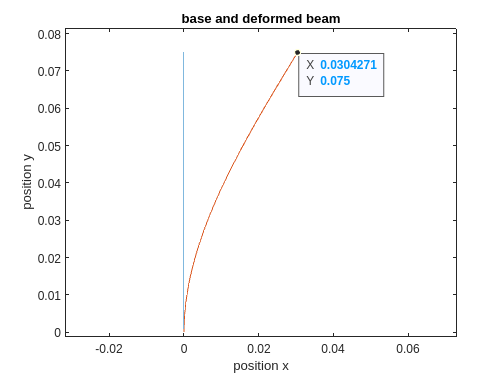


plot(x_base, y_base)
hold on
plot(x_deformed, y_deformed)
axis('equal')
xlabel('position x')
ylabel('position y')
title('base and deformed beam')
hold off

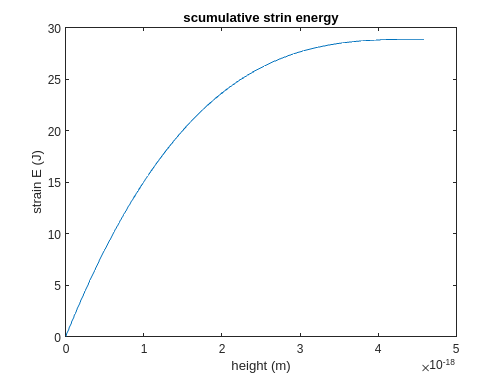

plot(x_base, strain_e)
title('scumulative strin energy')
xlabel('height (m)')
ylabel('strain E (J)')

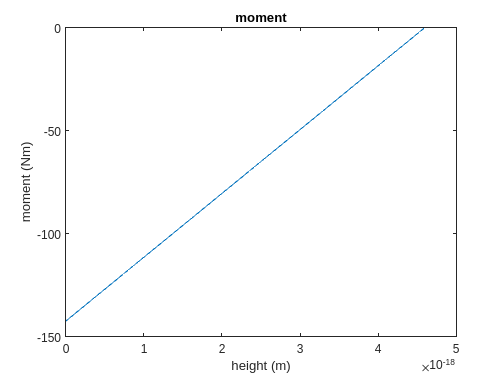

plot(x_base, moment)
title('moment')
xlabel('height (m)')
ylabel('moment (Nm)')

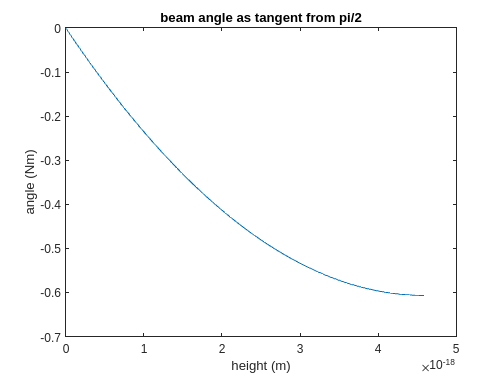

plot(x_base, ang)
title('beam angle as tangent from pi/2')
xlabel('height (m)')
ylabel('angle (Nm)')


% Manual stitching of beam sections
c2_moment = cross([0 0 0], [V; H; 0]); % section closest to applied load
s0_moment = cross([c2('height') -c2('length') 0], [V; H; 0]);
c1_moment = cross([c2('height')+s0('length')*sin(s0('beam_angle')) -c2('length')-s0('length')*cos(s0('beam_angle')) 0], [V; H; 0]);

straight0.couple = s0_moment(3);
curved.couple = c1_moment(3);
curved2.couple = c2_moment(3);

% solve deflections from loaded end out
% large curved section
curved.ba = 0;
[sHc1, sVc1, Htac1, Vtac1, Mc1, Ac1, Uc1] = curved.def(forces, 'linspace'); 

% straight section
straight0.ba = -Ac1(1);
straight0.bV = Vtac1(1) - sHc1(1); % difference between deflected and equellibrium
straight0.bH = Htac1(1) - sVc1(1); 
[sHs0, sVs0, Htas0, Vtas0, Ms0, As0, Us0] = straight0.def(forces, 'linspace');

% small curved section
curved2.ba = -Ac1(1)-As0(1);
curved2.bV = Vtas0(1) - sHs0(1);
curved2.bH = Htas0(1) - sVs0(1);
[sHc2, sVc2, Htac2, Vtac2, Mc2, Ac2, Uc2] = curved2.def(forces, 'linspace');

clf
hold on

% static
plot(sHc1, sVc1)
plot(sHs0+sHc1(1), sVs0+sVc1(1))
plot(sHc2+sHs0(1)+sHc1(1), sVc2+sVs0(1)+sVc1(1))

% deformed
plot(Vtac1, Htac1)
plot(Vtas0+sHc1(1), Htas0+sVc1(1))
plot(Vtac2+sHc1(1)+sHs0(1), Htac2+sVc1(1)+sVs0(1))

axis equal

function [x_base, y_base, x_deformed, y_deformed, M, ang, strain_e] = stitch(sections, forces)
    f = forces('f'); % is in the form [V; H]
    
    v_offset = 0; % buffer to be overwritten for each loop
    h_offset = 0;
    a_offset = 0;
    
    M = [];
    strain_e = [];
    ang = [];
    x_base = []; % build undeformed x state of beam for plotting
    y_base = []; % build undeformed y state of beam for plotting

    x_offset = 0;
    xdef_offset = 0;
    y_offset = 0;
    ydef_offset = 0;

    x_deformed = []; % absolute x position of deformed beam
    y_deformed = []; % absolute y position of deformed beam

    angle_offset = 0;

    for s = 1:size(sections)
        sec = sections(string(s)); % key in Map indicates order of sections
        height = 0; % sum as we iterate through beam sections to find moment
        length = 0;
        % sum remaining distance to point of load for moment calcualtion
        for s_other = s+1:size(sections)
            height = height + sections(string(s_other)).height;
            length = length + sections(string(s_other)).length;
        end
        
        moment = cross([height -length 0], [f(1); f(2); 0]);
        sec.couple = moment(3);
        sec.ba = a_offset;
        sec.bV = v_offset;
        sec.bH = h_offset;
%         
        [h_base, v_base, h_def, v_def, m, angle, energy] = sec.def(forces, 'linspace');
        h_base = h_base - h_base(1);
        v_base = v_base - v_base(1)
        h_def = h_def - h_def(1);
        v_def = v_def - v_def(1);

        M = [M m];
        strain_e = [strain_e energy];
        ang = [ang angle+angle_offset];

        x_base = [x_base h_base+x_offset];
        y_base = [y_base v_base+y_offset];

        x_deformed = [x_deformed h_def+xdef_offset]; % absolute x position of deformed beam
        y_deformed = [y_deformed v_def+ydef_offset]; % absolute y position of deformed beam

        x_offset = x_offset + h_base(end);
        y_offset = y_offset + v_base(end);
        xdef_offset = xdef_offset + h_def(end);
        ydef_offset = ydef_offset + v_def(end);

        angle_offset = angle(end);

%         a_offset = a_offset - angle(end);
        a_offset = a_offset + angle(end);
%         v_offset = v_def(end) - h_base(end);
%         h_offset = h_def(end) - v_base(end);    
        v_offset = v_def(end) - v_base(end);
        h_offset = h_def(end) - h_base(end);

    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [x_base, y_base, x_deformed, y_deformed, M, ang, strain_e] = stitch_shooting(sections, forces)
    f = forces('f'); % is in the form [V; H]
    
    v_offset = 0; % buffer to be overwritten for each loop
    h_offset = 0;
    a_offset = 0;
    
    M = [];
    strain_e = [];
    ang = [];
    x_base = []; % build undeformed x state of beam for plotting
    y_base = []; % build undeformed y state of beam for plotting

    x_offset = 0;
    xdef_offset = 0;
    y_offset = 0;
    ydef_offset = 0;

    x_deformed = []; % absolute x position of deformed beam
    y_deformed = []; % absolute y position of deformed beam

    angle_offset = 0;

    for s = 1:size(sections)
        while true
            sec = sections(string(s)); % key in Map indicates order of sections
            height = 0; % sum as we iterate through beam sections to find moment
            length = 0;
            % sum remaining distance to point of load for moment calcualtion
            for s_other = s+1:size(sections)
                height = height + sections(string(s_other)).height;
                length = length + sections(string(s_other)).length;
            end
            
            moment = cross([height -length 0], [f(1); f(2); 0]);
            sec.couple = moment(3);
            sec.ba = a_offset;
            sec.bV = v_offset;
            sec.bH = h_offset;
    %         
            [h_base, v_base, h_def, v_def, m, angle, energy] = sec.def(forces, 'linspace');
            h_base = h_base - h_base(1);
            v_base = v_base - v_base(1);
            h_def = h_def - h_def(1);
            v_def = v_def - v_def(1);
    
            M = [M m];
            strain_e = [strain_e energy];
            ang = [ang angle+angle_offset];
    
            x_base = [x_base h_base+x_offset];
            y_base = [y_base v_base+y_offset];
    
            x_deformed = [x_deformed h_def+xdef_offset]; % absolute x position of deformed beam
            y_deformed = [y_deformed v_def+ydef_offset]; % absolute y position of deformed beam
    
            x_offset = x_offset + h_base(end);
            y_offset = y_offset + v_base(end);
            xdef_offset = xdef_offset + h_def(end);
            ydef_offset = ydef_offset + v_def(end);
    
            angle_offset = angle(end);
    
    %         a_offset = a_offset - angle(end);
            a_offset = a_offset + angle(end);
    %         v_offset = v_def(end) - h_base(end);
    %         h_offset = h_def(end) - v_base(end);    
            v_offset = v_def(end) - v_base(end);
            h_offset = h_def(end) - h_base(end);
        end

    end
end